Exercise 3 Debug

addpath('C:\Program Files\casadi-windows-matlabR2016a-v3.5.5');
import casadi.*

Debug strategy 1: gradually increase R_col, see how the two objective functions evolute.

R_col_vals = 2:0.05:2.3;
nsamples = length(R_col_vals);
cost_vals = zeros(1,nsamples);
cost_mod_vals = zeros(1,nsamples);
completions = false(1,nsamples);
for i = 1:nsamples
    R_col = R_col_vals(i);
    [cost,cost_mod,OCP,foundSol,sol] = get_costs(R_col);
    cost_vals(i) = cost;
    cost_mod_vals(i) = cost_mod;
    completions(i) = foundSol;
    % make a video each time
    videoName = ['lin_tr_stat_obs_iter_',num2str(i)];
    pp.make_video_rectangles(OCP,sol,videoName,foundSol);
end

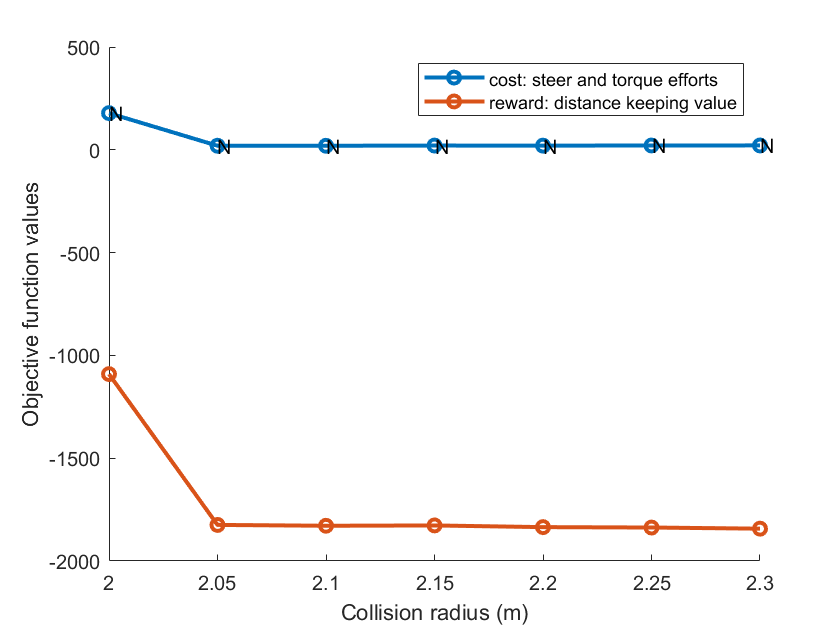

% plotting
figure();
hold on;
plot(R_col_vals,cost_vals,'-o','LineWidth',2);
% label whether solution is found
for i = 1:length(R_col_vals)
    if completions(i)
        text(R_col_vals(i),cost_vals(i),'Y');
    else
        text(R_col_vals(i),cost_vals(i),'N');
    end
end
plot(R_col_vals,cost_mod_vals,'-o','LineWidth',2);
xlabel('Collision radius (m)');
ylabel('Objective function values');
legend('cost: steer and torque efforts','reward: distance keeping value');

function [cost,cost_mod,OCP,foundSol,sol] = get_costs(R_col)
%get_costs Provide a value of R_col and produce solution costs
OCP = colliOCPv2(50);
OCP.build_basics();
% manually change the collision criteria
OCP.R_col = R_col; % collision radius (larger than 2 to fit the ziegler circle definition)
OCP.build_debug_var(); % for debug, run this function
OCP.add_control_bounds(); % use default bounds
% OCP.add_initial_conditions(); % use default I.C.'s
v_xb0 = 3; v_yb0 = 0; px0 = 0; py0 = 5; r0 = 0; psi0 = 0; omega_f0 = 10; omega_r0 = 10; delta0 = 0;
OCP.add_initial_conditions(v_xb0,v_yb0,px0,py0,r0,psi0,omega_f0,omega_r0,delta0); % driving straight
% OCP.add_initial_conditions(5,0,0,5,5,0,30,30,0); % initially spinning
OCP.add_path_constraints(); % use default constraints
OCP.add_ego_centers();
OCP.add_obstacle_centers(); % use default static obstacle
OCP.add_collision_constraint();
OCP.add_terminal_conditions(); % default T.C.'s
OCP.modify_objective(); % add obstacle CG repulsion into the objective.
OCP.set_solver_init();
% supress outputs
plugin_opts = struct('print_time',false);
solver_opts = struct('max_iter',200,'print_level',0);
% OCP.warm_start_init(sol);
try
    sol = OCP.solve(plugin_opts,solver_opts);
    foundSol = true;
catch
    sol = OCP.opti.debug;
    foundSol = false;
end

[cost,cost_mod] = calculate_cost(OCP,sol,foundSol);

end

function [cost,modified_cost] = calculate_cost(OCP,sol,foundSol)
    %calculate_cost Calculate the cost (objective) function value
    if ~foundSol
        sol = OCP.opti.debug;
    end

    cost = sum(sol.value((OCP.tau/1000).^2 + OCP.nu.^2));

    modified_cost = -sum(sol.value((OCP.px(2:end) - OCP.x_b).^2 ...
        + (OCP.py(2:end) - OCP.y_b).^2));
end